Elozo ora mechanikai kepet folytatjuk

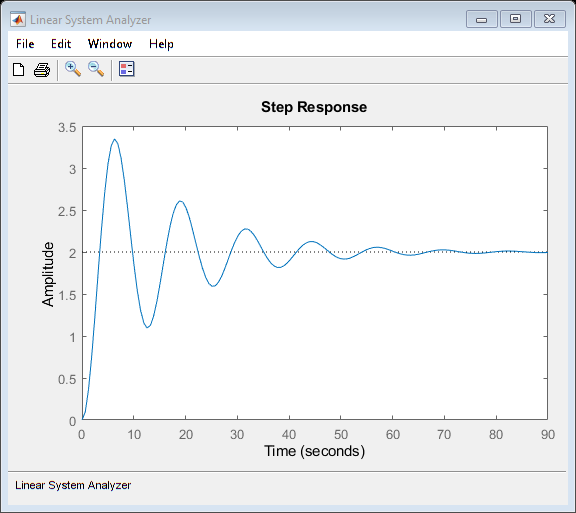

m=2; k=0.5; b=0.25;
Wp=1/k * tf(1, [m/k, b/k, 1]);

ltiview(Wp);

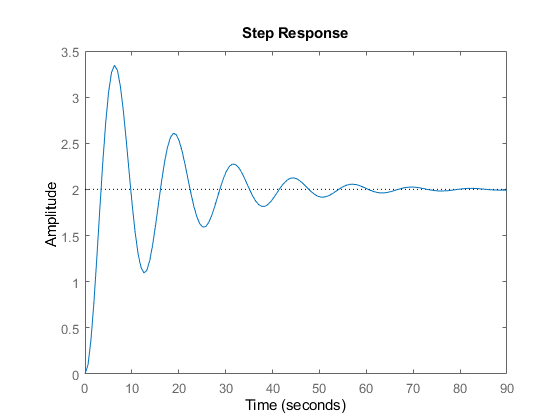

step(Wp);

polusok=roots(Wp.den{1})

polusok =   -0.0625 + 0.4961i
  -0.0625 - 0.4961i


Aranyos szabalyzok (P szab.)

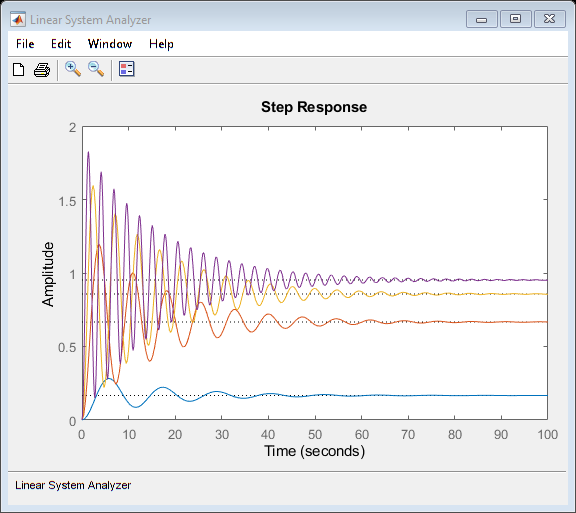

Wc1 = 0.1; Wc2=1; Wc3=3; Wc4=10;

W01 = Wc1*Wp;
W02 = Wc2*Wp;
W03 = Wc3*Wp;
W04 = Wc4*Wp;

Wcl1=feedback(W01, 1, -1);
Wcl2=feedback(W02, 1, -1);
Wcl3=feedback(W03, 1, -1);
Wcl4=feedback(W04, 1, -1);

ltiview(Wcl1, Wcl2,Wcl3, Wcl4);

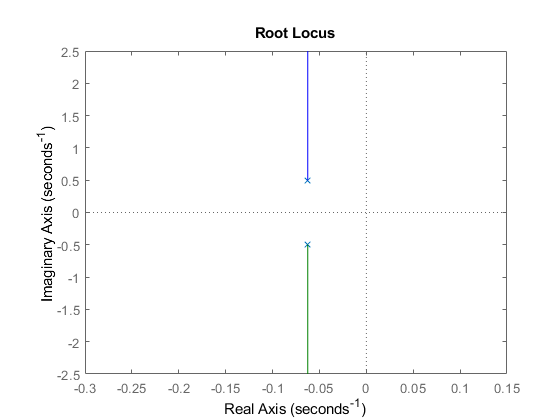


rlocus(W02)

Wc = Kc5 * (1+0.5s+4s^2)/s*(s+1) kiejtes miatt

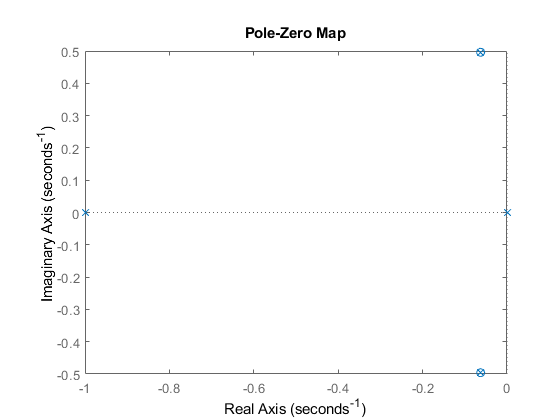

Wc5=tf([4 0.5 1], conv([1 0],[1 1]));
W05=Wc5*Wp;
pzmap(W05);

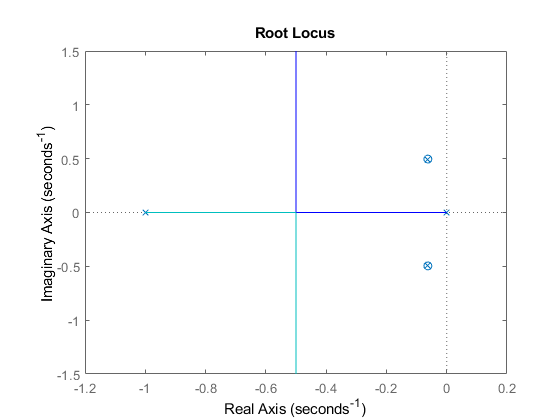

rlocus(W05);

Valtoztassuk az erositest a 0.707 csillapitashoz

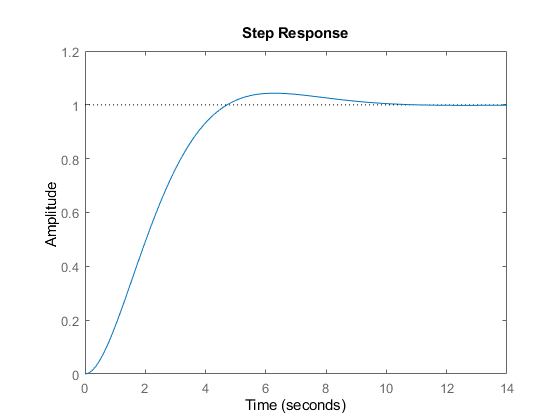

Wc5 = 0.25 * Wc5;
W05=Wc5*Wp;
Wcl5=feedback(W05, 1, -1);
step(Wcl5);

Polus-Zerus parok kiejtese

roots(W05.den{1})

ans =    0.0000 + 0.0000i
  -1.0000 + 0.0000i
  -0.0625 + 0.4961i
  -0.0625 - 0.4961i


W05m=minreal(W05);
roots(W05m.den{1})

ans =          0
   -1.0000


Beavatkozo jel megjelenitese

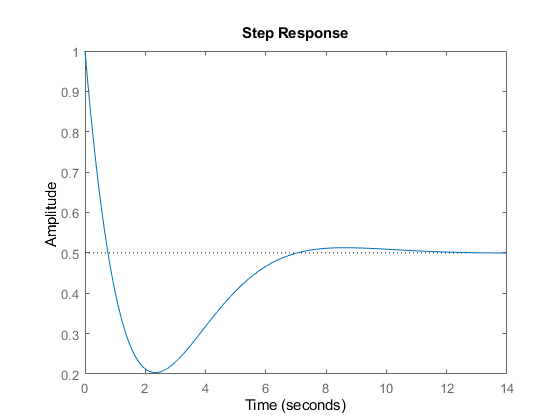

step(feedback(Wc5, Wp, -1));

Hol lesz instabil?

clear;clc;
A=5; T1=10;T2=4;T3=1;
Wp= tf(A, conv([T1 1], conv([T2 1],[T3 1])))

Wp =
 
              5
  --------------------------
  40 s^3 + 54 s^2 + 15 s + 1
 
Continuous-time transfer function.



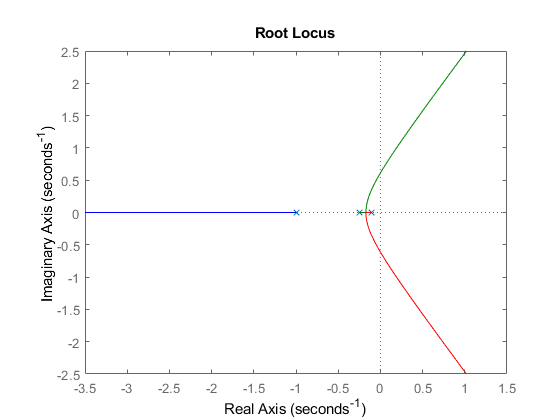

Wc=1;
W0=Wp*Wc;
rlocus(W0);

Instabilla tesszuk a gyokhelygorbe alapjan

clear;clc;
A=5; T1=10;T2=4;T3=1;
Wp= tf(A, conv([T1 1], conv([T2 1],[T3 1])))

Wp =
 
              5
  --------------------------
  40 s^3 + 54 s^2 + 15 s + 1
 
Continuous-time transfer function.



Wc=9;
W0=Wp*Wc; 

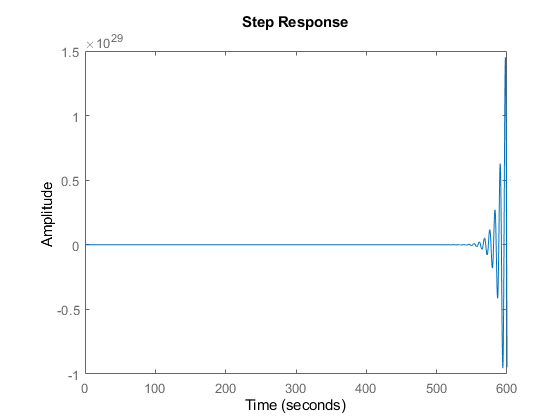

step(feedback(W0,1,-1));

Korbevetelek szamolasa

Instabilbol indulunk ki

clear; clc;
W0=tf([0.5 1],[1 -1 1]);
roots(W0.den{1})

ans =    0.5000 + 0.8660i
   0.5000 - 0.8660i


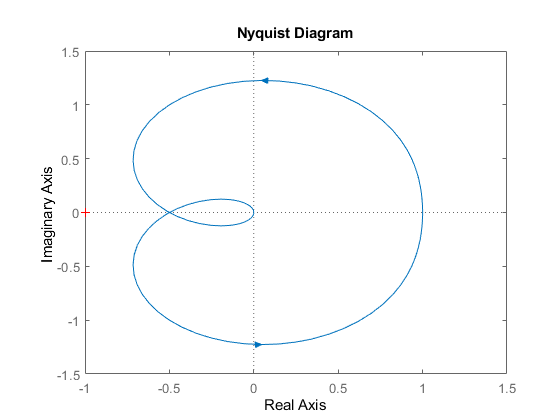

nyquist(W0);

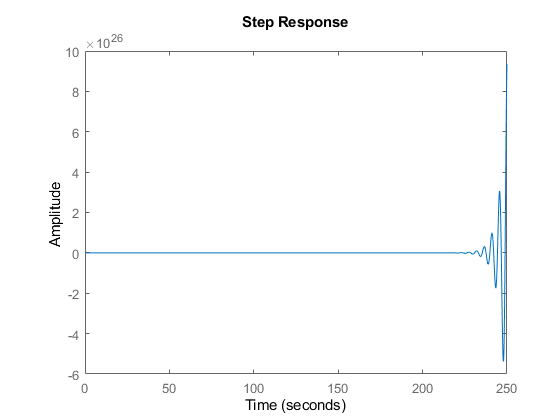

step(feedback(W0, 1, -1));

Felfujjuk

Mar stabil

W0=3*W0;
roots(W0.den{1})

ans =    0.5000 + 0.8660i
   0.5000 - 0.8660i


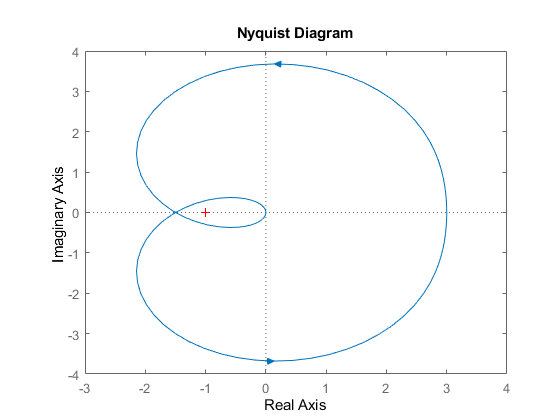

nyquist(W0);

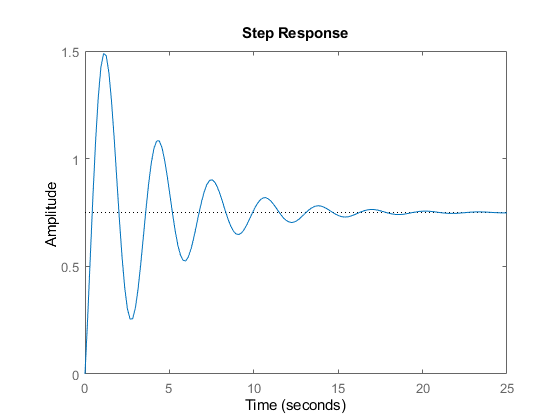

step(feedback(W0, 1, -1));